Show how we can add together several shorter exposures -- even with camera motion -- to simulate a single longer exposure

First, set up a default scenario

ieInit;
useScene = sceneMap("Macbeth Checker"); % Select desired scene
useScenario = ivScenario(useScene);

% ivScenario has defaults, but we can over-ride them
useScenario.exposureTime = 0.01;% in seconds
useScenario.clipLength = 0.05;% Long Exposure
useScenario.raysPerPixel = 512;
useScenario.fastPreview = 1;% divide rays & rez for previewing

% Save short exposure for later use
shortExposure = useScenario.exposureTime;

% calculate how many frames we need to add together
numFrames = round(useScenario.clipLength / useScenario.exposureTime);

Now we can modify settings or accept the default, and then create our video clips

sceneVideoClip(useScenario); % multi-capture

[INFO]: Read 25 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 2 assets; parsed up to line 109
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 1.202645 seconds.
[INFO]: Uploading data:
[INFO]: Sent 12,315 bytes  received 719 bytes  8,689.33 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-cnidl exec -it  pbrt-gpu-david5694 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/MacBethChecker/renderings/MacBethChecker.exr /home/david81/ISETRemoteRender/MacBethChecker/MacBethChecker.pbrt "
[INFO]: Rendered remotely in: 41.06 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 1,975,839 bytes  790,354.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/MacBethChecker.exr
Elapsed time is 0.567138 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,804 bytes  received 589 bytes  1,595.33 bytes/sec
[INFO]: Data u

% Single (longer) capture
useScenario.exposureTime = useScenario.clipLength;
sceneVideoClip(useScenario);

[INFO]: Read 25 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 2 assets; parsed up to line 109
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.883893 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,616 bytes  received 589 bytes  1,470.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-cnidl exec -it  pbrt-gpu-david5694 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/MacBethChecker/renderings/MacBethChecker.exr /home/david81/ISETRemoteRender/MacBethChecker/MacBethChecker.pbrt "
[INFO]: Rendered remotely in: 40.98 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 2,997,648 bytes  1,199,077.60 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/MacBethChecker.exr
Local cpCam ran  in: 89 seconds of CPU time.
Total cpCam ran  in: 70.6537 total seconds.


By default, results are in local/synthetic-scene-tests, labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

Typically the "start" frame is 001, so we've currently hard-coded that.

sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(shortExposure * 1000))),numFrames);
sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(useScenario.clipLength * 1000))),1);

NOTE: We need to move the generated files to generated, or put them there right away:)

Now we can compare the synthesized scene(s).

sceneHomeDir =  ivDirGet('computed');
% scene names have 3 codes:
% * exposureTime in ms
% * first frame in series (typically 001)
% * last frame in series (typically 001 or numFrames)
[sensorSingle, sensorMulti] = sceneCompare( ...
    fullfile(sceneHomeDir,sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(shortExposure*1000), 1, numFrames)), ...
    fullfile(sceneHomeDir, sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(useScenario.exposureTime*1000),1,1)), useScenario.exposureTime);

Denoised in: 89.483
Denoised in: 91.994


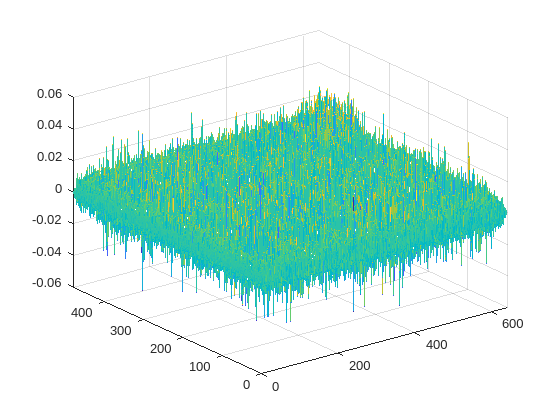

% Show results
mesh(sensorSingle.data.volts - sensorMulti.data.volts);

[ssimVal, ssimMap] = ssim(sensorSingle.data.volts, sensorMulti.data.volts);
fprintf('%f\n',ssimVal)

0.993156


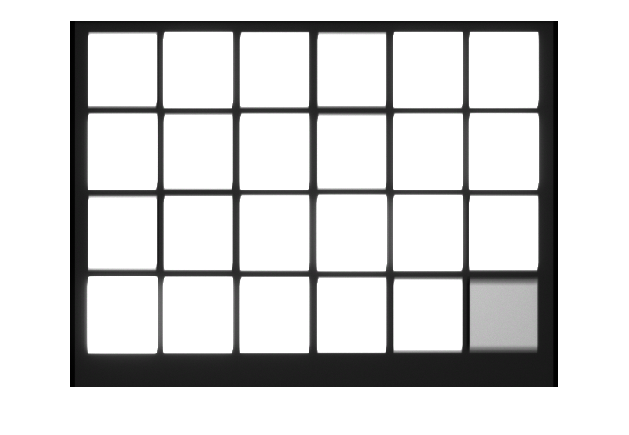

imshowpair(sensorSingle.data.volts,sensorMulti.data.volts,'falsecolor');

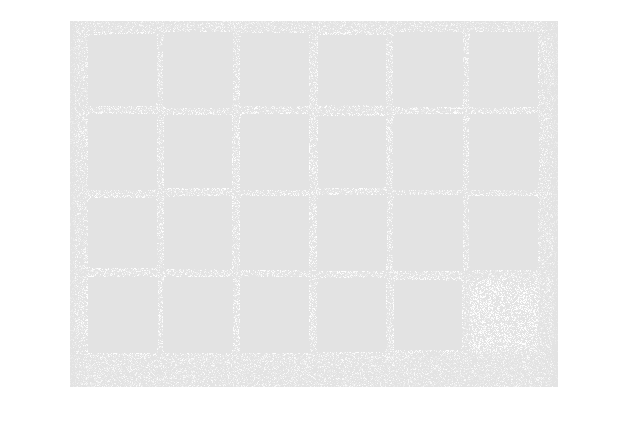

imshow(histeq(sensorSingle.data.volts - sensorMulti.data.volts));

function useScene = sceneMap(sceneLabel)
switch sceneLabel
    case 'Pavilion-Day'
        useScene = 'pavilion-day';
    case 'Paviioon-Night'
        useScene = 'pavilion-night';
    case "Macbeth Checker"
        useScene = 'MacBethChecker';
end
end